# LAB 5

## Potencies mod max

clear
A = [1 0 -1; 1 2 1; 2 2 3];

x= [1 1 1]';

n=50;

for i= 1:n
xaux= x;
    
z= A*x;

m= norm(z,'inf');

x= (1/m)*z;

if norm(x-xaux, 'inf') < eps
    break;
end
end

## Potencies mod min

clear

A = [1 0 -1; 1 2 1; 2 2 3];

x= [1 -1 1]';
n=50;

B=inv(A);

for i=1:n
    %z=B*x;
    z=A\x;
    xaux= x;
    
    m= norm(z,'inf');

    x= (1/m) * z;
    
    if norm(x - xaux) < eps
        break;
    end
end


## Ambdos amb nova mat

clear

A= -[1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];

[mod,vec,it] = potencies_min(A,[1 1 1 1]',50,eps);

[mod2,vec2,it2] = potencies_max(A,[1 1 1 1]',50,eps);


## Quocinent Rayleigh

clear

A= -[1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];

[mod,vec,it]= quocient_ray_max(A,[1 0 0 1]',50,eps)


## Factoritzacio QR

clear

A = [1 0 -1; 1 2 1; 2 2 3];
it=150;
k=0;
n=1;

while (k < it && n > eps)
[Q,R]= qr(A); %Q*R = A
A= R*Q;
n=norm(tril(A,-1),'inf');
k=k+1;
end


## Valors Singulars SVD (singular value decomposition)

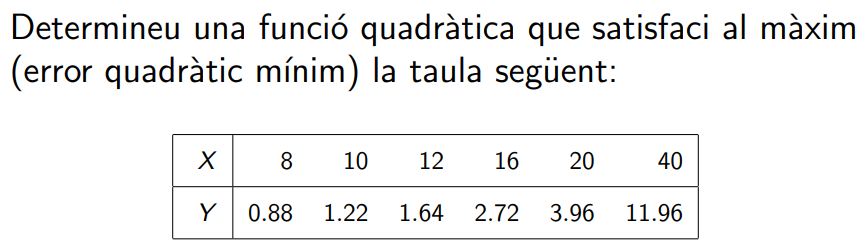

clear

x= [8 10 12 16 20 40];
y= [0.88 1.22 1.64 2.72 3.96 11.96]';
aux= ones(size(x,2),1);

A=[x'.^2,x', aux];

%plot(x,y,'*')
coeff= A\y

coeff =     0.0045
    0.1307
   -0.5166


[U,S,V]=svd(A);

%Pseudoinversa de S
auxS= S';
auxS= 1./auxS;
auxS(auxS == inf) = 0;

V*auxS*U'

ans =     0.0023    0.0010   -0.0001   -0.0018   -0.0029    0.0015
   -0.1277   -0.0617   -0.0038    0.0878    0.1470   -0.0415
    1.4360    0.8178    0.2722   -0.6011   -1.1839    0.2591



V*pinv(S)*U'

ans =     0.0023    0.0010   -0.0001   -0.0018   -0.0029    0.0015
   -0.1277   -0.0617   -0.0038    0.0878    0.1470   -0.0415
    1.4360    0.8178    0.2722   -0.6011   -1.1839    0.2591



%S'utilitzen per calcular pinv()
%pinv(A) pseudo inversa, no te perque ser quadrada
pinv(A)*y

ans =     0.0045
    0.1307
   -0.5166


## Practica 10

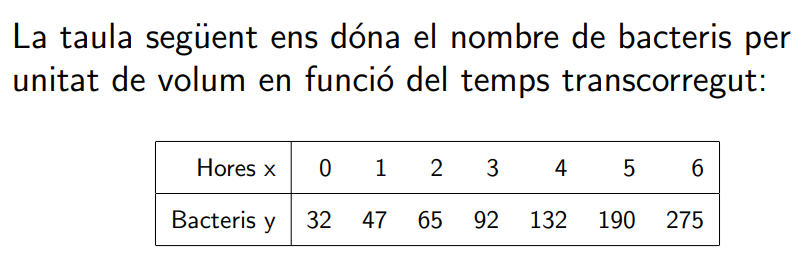

y=ab^x

ln y= ln a +x ln b

clear
x=[0 1 2 3 4 5 6];
y=[32 47 65 92 132 190 275]';

aux= ones(size(x,2),1);
A=[x',aux];
b= log(y);
coef=pinv(A)*b
z=fix(exp(polyval(coef,7)))
plot(x,y,'o',7,z,'r*')